### Probe-Drogue Capture Geometry

Question this file answers: is the drogue big enough, and shaped right, to catch the probe at the required offsets? The probe is fixed on the test stand; the drogue rides on the ABV.

How the offsets are defined: the probe and drogue share a centerline when perfectly lined up. The radial offset (SYS.07) is the ABV sitting 0.10 m to the side of that centerline, both when the approach starts and at contact. The angular offset (SYS.08) is the ABV turned 4°. In a combined test the ABV first moves 0.10 m to the side, then turns 4°.

Four checks. (1) Entry: the probe nose has to land inside the drogue mouth. (2) Sliding: the drogue walls have to be steep enough that the probe slides down them instead of sticking. (3) Length: how long a skirt is needed and what it costs in table space. (4) Seating: the probe has to seat at the bottom without wedging.

clear; clc; close all;

% ---- Requirements ----
radial_offset  = 0.10;          % m, SYS.07
angular_offset = deg2rad(4);    % rad, SYS.08
pos_error      = 0.005;         % m, how far off GNC/OptiTrack may place the ABV (estimate; confirm with table runs)
design_margin  = 0.010;         % m, extra room so runs that land slightly past 0.10 m are still caught

% ---- Geometry from Fusion CAD ----
r_nose   = 0.0143;  % m, probe nose radius (Internal Expander Mk3.5)
R_mouth  = 0.111;   % m, current drogue mouth radius (SatDoc Drogue Mk3.5 with skirt)
R_base   = 0.0554;  % m, where the skirt meets the original drogue opening
skirt    = 60;      % deg, skirt wall angle measured from the centerline
leadin   = 30;      % deg, original lead-in wall angle
inner    = 36;      % deg, inner cone wall angle
L_mouth  = 0.1715 + 0.1228;   % m, ABV center to the drogue mouth (half the ABV + drogue and plate)

% ---- How the ABV turns for the angular and combined tests ----
yaw_pivot = 'mouth';   % 'mouth'  = the ABV turns about the drogue mouth, so the mouth stays on its
                       %            line (matches the team's offset sketch). GNC has to shift the ABV
                       %            center sideways while it turns (see section 1b).
                       % 'center' = the ABV turns about its own center, so the mouth swings sideways.
dz_stand  = 0.000;     % m, height mismatch between the probe and drogue centerlines. The stand's
                       % table end is NOT level with the glass top (glass thickness unknown). MEASURE,
                       % then shim the stand so the two centerlines match.
c_seat   = 0.002;   % m, gap between probe and drogue cones when seated (team's 2 mm print tolerance)
L_seat   = 0.036;   % m, length over which the cones overlap when seated (CAD)

% ---- Friction (how grippy the surfaces are; ASSUMED typical dry values) ----
pair_name = ["PETG on PETG"; "Aluminum on PETG"; "Aluminum on aluminum"];
mu        = [0.45; 0.35; 0.60];
use_pair  = 1;      % current plan: printed PETG on printed PETG

### 1) Entry: is the mouth big enough?

The offset that matters is where the drogue MOUTH sits relative to the probe centerline. If the ABV turns about its own center, the mouth (about 0.29 m in front of the center) swings sideways about 20 mm and the angular and combined tests need a bigger drogue. If the ABV turns about the mouth, as in the team sketch, the mouth stays put. Any height mismatch between the probe and drogue centerlines adds to the offset too.

if strcmp(yaw_pivot, 'center')
    swing = L_mouth * sin(angular_offset);  % m, sideways swing of the mouth from the 4 deg turn
else
    swing = 0;                              % turning about the mouth leaves it in place
end
Test  = ["Radial (SYS.07)"; "Angular (SYS.08)"; "Combined (radial, then turn)"];
side  = [radial_offset; swing; radial_offset + swing];              % m, sideways offset at the mouth
off   = sqrt(side.^2 + dz_stand^2);                                  % m, total offset incl. height mismatch
R_req = off + pos_error + design_margin + r_nose;                    % m, mouth radius needed
pass  = repmat({'PASS'}, 3, 1);  pass(R_req > R_mouth) = {'FAIL'};
Entry = table(Test, off*1e3, R_req*1e3, repmat(R_mouth*1e3, 3, 1), pass, ...
    'VariableNames', {'Test', 'Offset at mouth (mm)', 'Mouth radius needed (mm)', 'Current mouth (mm)', 'Result'})

Entry = 3×5 table
                 Test                 Offset at mouth (mm)    Mouth radius needed (mm)    Current mouth (mm)     Result 
    ______________________________    ____________________    ________________________    __________________    ________

    "Radial (SYS.07)"                         100                      129.3                     111            {'FAIL'}
    "Angular (SYS.08)"                          0                       29.3                     111            {'PASS'}
    "Combined (radial, then turn)"            100                      129.3                     111            {'FAIL'}



cap_now = R_mouth - r_nose - pos_error - design_margin;
fprintf('The current drogue catches offsets up to %.0f mm (after margins); SYS.07 asks for %.0f mm.\n', ...
    cap_now*1e3, radial_offset*1e3);

The current drogue catches offsets up to 82 mm (after margins); SYS.07 asks for 100 mm.


fprintf('Turning about the %s. Combined test needs a %.0f mm mouth radius.\n', yaw_pivot, R_req(3)*1e3);

Turning about the mouth. Combined test needs a 129 mm mouth radius.


fprintf('(Turning about the ABV center instead would need %.0f mm.)\n', ...
    (sqrt((radial_offset + L_mouth*sin(angular_offset))^2 + dz_stand^2) + pos_error + design_margin + r_nose)*1e3);

(Turning about the ABV center instead would need 150 mm.)


### 1b) What GNC has to do to turn about the drogue mouth

Thrusters naturally turn the ABV about its own center. To make the drogue mouth stay on its line (the sketch), the guidance code should aim the ABV CENTER at a point set back from the desired mouth position along the turned direction. In other words: decide where the mouth should be, then work backward to where the center must go.

% Desired drogue-mouth position (x toward the probe, y sideways) and yaw for the combined test:
mouth_target = [0, radial_offset];          % m, mouth 0.10 m off the centerline (x measured at the mouth)
psi = angular_offset;                       % rad
center_target = mouth_target - L_mouth*[cos(psi), sin(psi)];   % m, where GNC should put the ABV center
center_noturn = mouth_target - L_mouth*[1, 0];                  % m, center for the radial-only test
shift = center_target - center_noturn;
fprintf('For the combined test, the ABV center goes %.1f mm sideways (opposite the way the nose turns)\n', abs(shift(2))*1e3);

For the combined test, the ABV center goes 20.5 mm sideways (opposite the way the nose turns)


fprintf('and %.1f mm closer to the probe than in the radial-only test. Formula for the guidance code:\n', abs(shift(1))*1e3);

and 0.7 mm closer to the probe than in the radial-only test. Formula for the guidance code:


fprintf('  center = mouth_target - L*[cos(yaw), sin(yaw)],  L = %.3f m (ABV center to drogue mouth)\n', L_mouth);

  center = mouth_target - L*[cos(yaw), sin(yaw)],  L = 0.294 m (ABV center to drogue mouth)


### 2) Sliding: are the walls steep enough?

If a wall is too flat (angle from the centerline too large), friction holds the probe in place instead of letting it slide inward. The steepest allowed angle is 90° minus the friction angle minus the 4° yaw.

phi     = atand(mu);                             % deg, friction angle
max_ang = 90 - phi - rad2deg(angular_offset);    % deg, flattest wall that still slides
SlideCheck = table(pair_name, mu, max_ang, max_ang - skirt, max_ang - leadin, max_ang - inner, ...
    'VariableNames', {'Surfaces', 'Friction', 'Flattest wall that slides (deg)', ...
    'Margin, 60° skirt (deg)', 'Margin, 30° lead-in (deg)', 'Margin, 36° inner cone (deg)'})

SlideCheck = 3×6 table
           Surfaces           Friction    Flattest wall that slides (deg)    Margin, 60° skirt (deg)    Margin, 30° lead-in (deg)    Margin, 36° inner cone (deg)
    ______________________    ________    _______________________________    _______________________    _________________________    ____________________________

    "PETG on PETG"              0.45                  61.772                          1.7723                     31.772                         25.772           
    "Aluminum on PETG"          0.35                   66.71                            6.71                      36.71                          30.71           
    "Aluminum on aluminum"       0.6                  55.036                         -4.9638                     25.036     

mu_stick = tand(90 - skirt - rad2deg(angular_offset));
fprintf('The 60° skirt sticks if friction exceeds %.2f. Printed PETG on PETG is roughly 0.3-0.6,\n', mu_stick);

The 60° skirt sticks if friction exceeds 0.49. Printed PETG on PETG is roughly 0.3-0.6,


fprintf('so the skirt is close to sticking. A 45-50° skirt keeps a comfortable margin.\n');

so the skirt is close to sticking. A 45-50° skirt keeps a comfortable margin.


### 3) Skirt length for the required mouth

R_target = R_req(1);                          % mouth needed for the radial test
ang  = [45; 50; 55; 60];                      % deg, skirt angles to compare
Lsk  = (R_target - R_base) ./ tand(ang);      % m, skirt length
mar  = max_ang(use_pair) - ang;               % deg, sliding margin
SkirtOptions = table(ang, Lsk*1e3, mar, ...
    'VariableNames', {'Skirt angle (deg)', 'Skirt length for the needed mouth (mm)', 'Sliding margin, PETG (deg)'})

SkirtOptions = 4×3 table
    Skirt angle (deg)    Skirt length for the needed mouth (mm)    Sliding margin, PETG (deg)
    _________________    ______________________________________    __________________________

           45                              73.9                              16.772          
           50                            62.009                              11.772          
           55                            51.745                              6.7723          
           60                            42.666                              1.7723          


fprintf('Current skirt: %.0f mm long. Any added length comes out of the ABV''s approach room (about 3 m), which is negligible.\n', ...
    (R_mouth - R_base)/tand(skirt)*1e3);

Current skirt: 32 mm long. Any added length comes out of the ABV's approach room (about 3 m), which is negligible.


### 4) Seating at the bottom

seat_ok = rad2deg(2*c_seat / L_seat);          % deg, misalignment the seated cones accept
fprintf('A %.0f mm gap over %.0f mm of overlap accepts %.1f° of misalignment (the test needs 4°).\n', ...
    c_seat*1e3, L_seat*1e3, seat_ok);

A 2 mm gap over 36 mm of overlap accepts 6.4° of misalignment (the test needs 4°).


fprintf('Because the drogue mouth is ahead of the ABV center, wall contact turns the ABV back toward\n');

Because the drogue mouth is ahead of the ABV center, wall contact turns the ABV back toward


fprintf('the centerline, so the cones also reduce the yaw error before the probe seats.\n');

the centerline, so the cones also reduce the yaw error before the probe seats.


### Plots

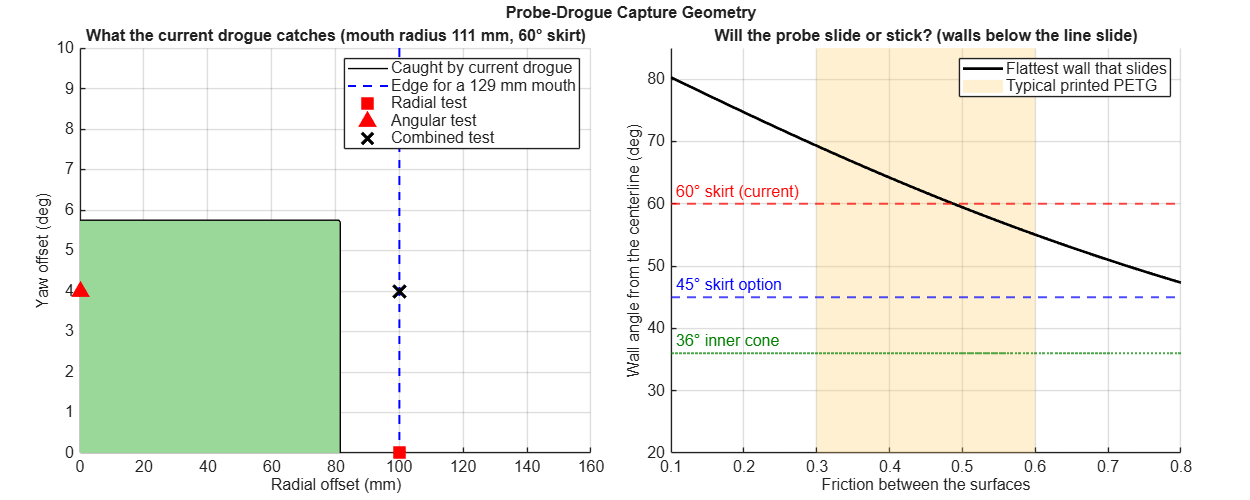

fig = figure('Name', 'Capture Geometry', 'Position', [80 80 1250 500]);
theme(fig, 'light');
tl = tiledlayout(1, 2, 'TileSpacing', 'compact', 'Padding', 'compact');

nexttile; hold on;
dr  = linspace(0, 0.16, 161);  yaw = deg2rad(linspace(0, 10, 101));
[DR, YW] = meshgrid(dr, yaw);
pivot = double(strcmp(yaw_pivot, 'center'));
reach = sqrt((DR + pivot*L_mouth*sin(YW)).^2 + dz_stand^2) + pos_error + design_margin + r_nose;
slide = skirt <= 90 - phi(use_pair) - rad2deg(YW);
contourf(DR*1e3, rad2deg(YW), double(reach <= R_mouth & slide), [0.5 0.5], 'LineColor', 'k');
colormap(gca, [1 1 1; 0.6 0.85 0.6]);
contour(DR*1e3, rad2deg(YW), reach - R_req(1), [0 0], 'b--', 'LineWidth', 1.5);
plot(radial_offset*1e3, 0, 'rs', 'MarkerSize', 11, 'MarkerFaceColor', 'r');
plot(0, 4, 'r^', 'MarkerSize', 11, 'MarkerFaceColor', 'r');
plot(radial_offset*1e3, 4, 'kx', 'MarkerSize', 13, 'LineWidth', 2.5);
xlabel('Radial offset (mm)'); ylabel('Yaw offset (deg)');
title(sprintf('What the current drogue catches (mouth radius %.0f mm, %d° skirt)', R_mouth*1e3, skirt));
legend('Caught by current drogue', sprintf('Edge for a %.0f mm mouth', R_req(1)*1e3), ...
       'Radial test', 'Angular test', 'Combined test', 'Location', 'northeast');
grid on;

nexttile; hold on;
mu_sw = linspace(0.1, 0.8, 100);
plot(mu_sw, 90 - atand(mu_sw) - 4, 'k-', 'LineWidth', 2, 'DisplayName', 'Flattest wall that slides');
yline(skirt,  'r--', '60° skirt (current)', 'LineWidth', 1.5, 'HandleVisibility', 'off', 'LabelHorizontalAlignment', 'left');
yline(45, 'b--', '45° skirt option', 'LineWidth', 1.5, 'HandleVisibility', 'off', 'LabelHorizontalAlignment', 'left');
yline(inner,  'Color', [0 0.5 0], 'LineStyle', ':', 'Label', '36° inner cone', 'LineWidth', 1.5, 'HandleVisibility', 'off', 'LabelHorizontalAlignment', 'left');
xregion(0.3, 0.6, 'FaceColor', [1 0.8 0.4], 'DisplayName', 'Typical printed PETG');
xlabel('Friction between the surfaces'); ylabel('Wall angle from the centerline (deg)');
title('Will the probe slide or stick? (walls below the line slide)');
ylim([20 85]); legend('Location', 'northeast'); grid on;

title(tl, 'Probe-Drogue Capture Geometry', 'FontWeight', 'bold');
fontsize(fig, 12, 'points');